LII Model Parameters Based on Lemaire et al.

% Laser-Induced Incandescence (LII) Model
%
% Based on:
% Lemaire, R., Menanteau, S. (2021)
% "Modeling laser-induced incandescence of Diesel soot"
% Applied Physics B, 127:138
% https://doi.org/10.1007/s00340-021-07665-y
%
% This implementation reproduces the base model from the paper.
% No experimental CERL data is included in this repository.

clear; clc;
params.c = 2.998e10; % Speed of Light [cm/s] (Lemaire 2021, Appendix)
params.e_charge = 1.60218e-19; % Electron charge [C] (Lemaire 2021, Appendix)
% Diffusion constants
params.A0_C2 = 9.0235e-4; % [W*cm^-1*K^-1] (Lemaire 2021, Appendix)
params.A0_C3 = 5.7683e-4; % [W*cm^-1*K^-1](Lemaire 2021, Appendix)
params.A1_C2 = 3.8475e-7; % [W*cm^-1*K^-2](Lemaire 2021, Appendix)
params.A1_C3 = 1.8429e-7; % [W*cm^-1*K^-2](Lemaire 2021, Appendix)
params.Dh = @(a) 1.99345 + 0.30224*a - 0.11276*a.^2; % Scaling factor(Lemaire 2021, Appendix)
params.Dp_ref = 34e-7; % Reference diameter [cm](Lemaire 2021, Appendix)
params.ka = @(Tp) 4.935e23 .* exp(-1.255e5 ./ (8.314 .* Tp)); % A-site oxidation [s^-1*cm^-2*bar^-1](Lemaire 2021, Appendix)
params.kb = @(Tp) 4.935e21 .* exp(-6.352e4 ./ (8.314 .* Tp)); % B-site oxidation [s^-1*cm^-2*bar^-1](Lemaire 2021, Appendix)
params.kB = 1.381e-23; % Boltzmann constant [J/K]
params.kdiss = @(Tp) 1e18 .* exp(-9.6e5 ./ (8.314 .* Tp)); % pyrolysis rate constant [s^-1](Lemaire 2021, Appendix)
params.kg = @(Tg) 1.0811e-4 + 5.1519e-7 .* Tg;   % [W/cm/K] Thermal Conductivity(Lemaire 2021, Appendix)
params.kh = @(a) 1.04476 + 0.22329*a + 7.14286e-3*a.^2; % Scaling factor for D_HC(Lemaire 2021, Appendix)
params.kim = @(Tp) 1e8 .* exp(-8.3e4 ./ (8.314 .* Tp));   % Interstitial Migration [s^-1](Lemaire 2021, Appendix)
params.kp = 1.38065e-22; % Boltzmann constant in bar*cm^3/K(Lemaire 2021, Appendix)
params.kt = @(Tp) 3.79e27 .* exp(-4.06e5 ./ (8.314 .* Tp)); % Site Transformation [s^-1*cm^-2](Lemaire 2021, Appendix)
params.kvmig = @(Tp) 1.5e17 .* exp(-6.7e5 ./ (8.314 .* Tp)); % Vacancy Migration [s^-1](Lemaire 2021, Appendix)

params.kz = @(Tp) 21.02 .* exp(1.713e4 ./ (8.314 .* Tp)); % Oxide formation [bar^-1](Lemaire 2021, Appendix)
params.me = 9.1095e-35; % electron mass [J*s^2*cm^-2](Lemaire 2021, Appendix)
params.NA = 6.02214e23; % Avogadro number [mol^-1](Lemaire 2021, Appendix)
params.Ns_a = 3.8e15; % density of carbon atoms (annealed) [cm^-2](Lemaire 2021, Appendix)
params.Ns_s = 2.8e15; % density of carbon atoms (unannealed) [cm^-2](Lemaire 2021, Appendix)
params.p_Np= 1; % PDF of aggregate size
params.PO2 = @(Pg) 0.21*Pg; % O2 partial pressure [bar](Lemaire 2021, Appendix)
params.Pref = 1.01325; % reference pressure [bar](Lemaire 2021, Appendix)
params.R = 8.3145; % universal gas constant [J/mol/K](Lemaire 2021, Appendix)
% Gas constants
params.Rm = 8.3145e7; % [erg*cm^-2*mol^-1*K^-1](Lemaire 2021, Appendix)
params.Rp = 83.145; % [bar*cm^3*mol^-1*K^-1](Lemaire 2021, Appendix)
params.T_f_CO = 790; % temperature where CO molecules emit [K](Lemaire 2021, Appendix)
params.Tref = 0; % reference temperature [K](Lemaire 2021, Appendix)
% Given values: (Lemaire 2021, Appendix)
params.Tc_C1 = 4603.48;
params.Tc_C2 = 4456.59;
params.Tc_C3 = 4136.78;
params.Tc_C4 = 4949.74;
params.Tc_C5 = 4772.87;
params.Wj = 12.01;   % species weight (C clusters) per j [g/mol](Lemaire 2021, Appendix)
params.WO2 = 31.99; % oxygen molecular weight [g/mol](Lemaire 2021, Appendix)
params.Xd= 1e-2; % defect density (initial)(Lemaire 2021, Appendix)
params.gamma = @(Cp_m) Cp_m ./ (Cp_m - params.R); % Cp/(Cp - R)(Lemaire 2021, Appendix)
% Formation by thermal Sublimation enthalpy
params.dH_sub = @(Tp) -12.326 .* Tp + 8.545e5;   % [J/mol](Lemaire 2021, Appendix)
% Interstitial migration
params.dH_mig = -1.9e4;   % [J/mol](Lemaire 2021, Appendix)
% Vapor species formation enthalpies (C1–C5) (Lemaire 2021, Appendix)
params.dH_C1 = @(Tp) -5.111 .* Tp + 7.266e5;
params.dH_C2 = @(Tp) -12.326 .* Tp + 8.545e5;
params.dH_C3 = @(Tp) -26.921 .* Tp + 8.443e5;
params.dH_C4 = @(Tp) -2.114e-3 .* Tp.^2 - 7.787 .* Tp + 9.811e5;
params.dH_C5 = @(Tp) -2.598e-3 .* Tp.^2 - 7.069 .* Tp + 9.898e5;
% Oxidation enthalpy (Lemaire 2021, Appendix)
params.dH_ox = @(Tp) 2.8901e-14 .* Tp.^5 - 4.9868e-10 .* Tp.^4 + 3.3206e-6 .* Tp.^3 - 1.0307e-2 .* Tp.^2 + 7.9303 .* Tp - 1.1221e5;
% Vacancy migration (Lemaire 2021, Appendix)
params.dH_vmig = -1.4e5; % [J/mol]
% Photodesorption enthalpies
params.dH_lambdan_a = 3.4e5; % annealed soot [J/mol](Lemaire 2021, Appendix)
params.lambda0 = 1; % arbitrary wavelength [cm](Lemaire 2021, Appendix)
% Annealed soot density
params.rho_a = @(Tp) 2.6 - 1e-4 .* Tp; % [g/cm^3](Lemaire 2021, Appendix)
% Unannealed soot density
params.rho_s = @(Tp) 2.3031 - 7.3106e-5 .* Tp; % [g/cm^3](Lemaire 2021, Appendix)
params.phi = 7.37e-19; % [J](Lemaire 2021, Appendix)
h = 6.626e-34;
params.Dp = 16.4e-7; % cm
params.Np = 1; % assumption as suggested
params.Tg = 1850; % K
params.lambda_l = 1064e-7; % cm
params.F = 0.2; % J/cm^2 laser fluence
params.t_l = 8e-9; % s pulse duration (Bladh 2008)
params.Xa = 0; % no annealing
params.E_m = 0.23; % refractive index function
params.Ea_m = 0.23; % placeholder since Xa=0
params.B_lambda1_s = 1.15; % J/cm^2 saturation coefficient
params.B_lambda1_a = 1.15; % placeholder
params.hNp = NaN; % calculated later
params.n = 2; % two photon process
params.c_s = 2.1;  % J/g/K (Bladh 2004)
params.c_a = 2.1;  % J/g/K
params.rho_s = @(Tp) (2.3031 - 7.3106e-5 .* Tp); % g/cm^3
params.rho_a = @(Tp) (2.6 - 1e-4 .* Tp); % g/cm^3
params.c = 2.998e10; % cm/s
params.kB = 1.381e-23; % J/K
params.R = 8.3145; % J/mol/K
params.Ntot = 1e8; % cm^-3 assumption
params.Dp_ref = 34e-7; % cm
params.lambda0 = 1; % cm
c = params.c;
% Unknown parameters:
params.fa = 1;
params.f1_a = 1;
params.f1_s = 1;
tl   = params.t_l;
gamma_star = 1.4; % assumption
params.alpha_T = 0.49; % Lemaire 2021
params.Pg = 1.01325; % assumption [bar]
params.Mg = 29/ params.NA; % g/molecule assumption
Tdelta = @(Tp)params.Tg; % assumption
lambda_rad = linspace(200e-7,5000e-7,4000);
kg = @(T) (1.0811e-4 + 5.1519e-7 .* T); % W/cm/K
gamma_g = 1.4; % assumption
f_eucken = 1.9; % assumption
CpCO = 29.14; % J/mol/K assumption
CpO2 = 29.36; % J/mol/K assumption
params.f = (9 * 1.4 - 5) / 4;
sigma_2 = 2.4e-15; % cm^-2 (Michelsen 2003)
sigma_3 = 4.5e-15; % cm^-2 (Michelsen 2003)
params.Wj = [12.011 24.022 36.033 48.044 60.055];
% Source: Lemaire 2021 Appendix
params.alpha_j = [0.5 0.5 0.1 1e-4 1e-4];
% Molecular collision cross sections [cm^2]
% Michelsen 2003 values
params.sigma_C2 = 2.4e-15;
params.sigma_C3 = 4.5e-15;
params.f = (9*1.4 - 5)/4;
params.Tref = 300;
params.dH_C1 = @(Tp) -5.111 .* Tp + 7.266e5;
params.dH_C2 = @(Tp) -12.326 .* Tp + 8.545e5;
params.dH_C3 = @(Tp) -26.921 .* Tp + 8.443e5;
params.dH_C4 = @(Tp) -2.114e-3 .* Tp.^2 - 7.787 .* Tp + 9.811e5;
params.dH_C5 = @(Tp) -2.598e-3 .* Tp.^2 - 7.069 .* Tp + 9.898e5;
params.dH_lambdan_a = 3.4e5;
params.dH_lambdan_s = 1.7e5;
params.dH_diss = @(Tp) -12.326 .* Tp + 8.545e5;
params.Tc_C1 = 4603.48;
params.Tc_C2 = 4456.59;
params.Tc_C3 = 4136.78;
params.Tc_C4 = 4949.74;
params.Tc_C5 = 4772.87;

To solve the ODE, in this we consider the equation dU/dt = Qdot_abs and then simplifying that with respect to the equations given in Lemaire 2021.

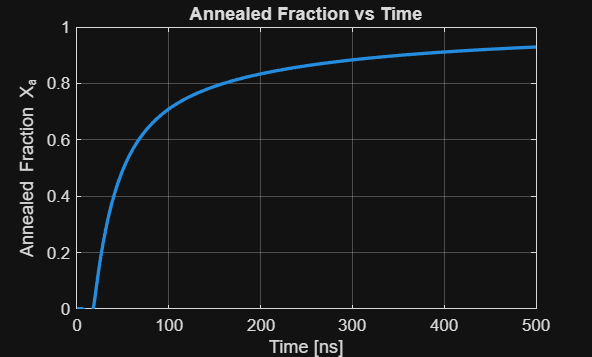

tspan = [0 500e-9];
opts = odeset('RelTol',1e-6,'AbsTol',1e-6);

Nc0 = (pi/6) .* params.Dp.^3 .* params.rho_s(params.Tg) .* params.NA ./ 12.011;
Nd0 = params.Xd .* Nc0;
Y0 = [params.Tg;params.Dp; Nd0];
[t,Y] = ode15s(@(t,Y) LII_odes(t,Y,params), tspan, Y0, opts);

Tp = Y(:,1);
Dp = Y(:,2);
Nd = Y(:,3);
Nc = (pi/6) .* Dp.^3 .* params.rho_s(Tp) .* params.NA ./ 12.011;
Xa = 1 - Nd ./ (params.Xd .* Nc);

figure
plot(t*1e9,Xa,'LineWidth',2)
xlabel('Time [ns]')
ylabel('Annealed Fraction X_a')
title('Annealed Fraction vs Time')
xlim([0 500])
ylim([0 1])
grid on

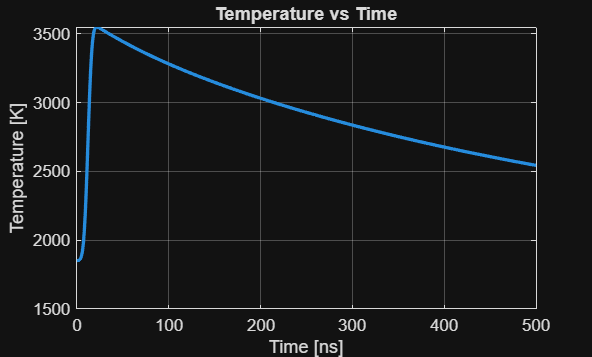


function dYdt = LII_odes(t,Y,params)

Tp = Y(1);
Dp = Y(2);
Nd = Y(3);

h = 6.626e-34;
Np = params.Np;
lambda_l = params.lambda_l;
F = params.F;
n = params.n;
Em = params.E_m;
Ea_m = params.Ea_m;
fa = params.fa;
f1s = params.f1_s;
f1a = params.f1_a;
B1s = params.B_lambda1_s;
B1a = params.B_lambda1_a;
Nss = params.Ns_s;
Nsa = params.Ns_a;
c = params.c;
rho_s = params.rho_s(Tp);
rho_a = params.rho_a(Tp);

Nc = (pi/6) .* Dp.^3 .*rho_s .* params.NA ./ 12.011;
Xa = 1 - (Nd ./ (params.Xd .* Nc));
Xa = max(0,min(1,Xa));

rho_eff = rho_s .* (1 - Xa) + rho_a .* Xa;
Cp_eff = params.c_s .* (1 - Xa) + params.c_a .* Xa;

% Gaussian Pulse
tl = params.t_l;
t0 = 1.5 * tl;
q_exp = @(t) exp(-4*log(2)*((t - t0)/tl).^2);
t_test = linspace(0,6*tl,1000);
norm_q = trapz(t_test,q_exp(t_test));
q_exp_norm = @(t) q_exp(t)./norm_q;
I = @(t) F .* q_exp(t);

% Qabs
alpha1_prime = (1.0209 - 24.0657 .* (log((lambda_l.*params.Dp_ref)./(params.lambda0 .* Dp)) ./ ((lambda_l.*params.Dp_ref)./(params.lambda0 .* Dp))) + 2244.37 .* (((lambda_l.*params.Dp_ref)./(params.lambda0 .* Dp)).^(-1.5))) .^(-1);
alpha2_prime = (0.9871 + 2.4878 .* (log((lambda_l.*params.Dp_ref)./(params.lambda0 .* Dp)) ./ ((lambda_l.*params.Dp_ref)./(params.lambda0 .* Dp)))) .^(-1);
hinfNp = 1.11 .* alpha1_prime.^2 .* Np.^(2 .* (alpha2_prime - 1));
hNp = hinfNp + (1 - hinfNp) .* exp(-(2/3) .* (Np -1).^(0.5));
qn_test = q_exp_norm(t_test).^n;
norm_qn = trapz(t_test,qn_test);
B_lambdan_s = 0.41;
B_lambdan_a = 0.41;
sigma_lambdan_s = 4.2e-10;
sigma_lambdan_a = 4.2e-10;
k_ls = (1 - Xa) .* (lambda_l ./ (n .* h .* c)) .* ((sigma_lambdan_s .* pi .* Dp.^3 .* Nss)./6) .* (B_lambdan_s.^(-n)) .* (1 ./ norm_qn) .* (1 - exp(-((I(t)./B_lambdan_s).^n)));
k_la = Xa .* (lambda_l ./ (n .* h .* c)) .* ((sigma_lambdan_a .* pi .* Dp.^3 .* Nsa)./6) .* (B_lambdan_a.^(-n)) .* (1 ./ norm_qn) .* (1 - exp(-((I(t)./B_lambdan_a).^n)));
Cabs_multi_s = (1 - Xa) .* (pi^2 .* Dp.^3 ./ lambda_l) .* Em .* hNp .* Np;
Cabs_multi_a = Xa .* (pi^2 .* Dp.^3 ./ lambda_l) .* fa .* Ea_m .* hNp .* Np;
Qabs = Cabs_multi_s .* f1s .* (B1s./norm_q) .* (1-exp(-(F .* q_exp(t))./B1s)) + Cabs_multi_a .* f1a .* (B1a./norm_q) .* (1-exp(-(F .* q_exp(t))./B1a)) + Np .* n .* (h*c/lambda_l) .* (k_ls + k_la);

% Qox
CpCO = 29.14;
CpO2 = 29.36;
Po2 = 0.21 * params.Pg;
chiA = @(Tp) 1 ./ (1 + (params.kt(Tp) ./ (params.kb(Tp) .* Po2)));
Zox = (Po2 ./ (params.kp .* params.Tg)) .* sqrt((params.Rm .* params.Tg) ./ (2 .* pi .* params.WO2));
kox_a = (2.8 .* Zox ./ sqrt(params.Tg)) .* exp(-1.4e5 ./ (params.R .* Tp)) .* Xa;
term1 = (params.ka(Tp) .* chiA(Tp)) ./ (1 + params.kz(Tp) .* Po2);
term2 = params.kb(Tp) .* (1 - chiA(Tp));
kox_s = 12 .* Po2 .* (term1 + term2) .* (1 - Xa);
dMpdt_ox = (-2 .* pi .* Dp.^2 .* 12.011 .* (kox_a + kox_s)) ./ params.NA;
Hox_term = (CpCO .* (params.T_f_CO - params.Tref)) - 0.5 .* (CpO2 .* (params.Tg - params.Tref)) + (params.R ./ 2) .* (params.T_f_CO - params.Tg) + params.dH_ox(Tp);
Qox = Np .* (1 ./ 12.011) .* Hox_term .* dMpdt_ox;

% Qrad
lambda_rad = linspace(200e-7,5e-4,20000);
Qrad = 8 .* pi .* h .* c.^2 .* trapz(lambda_rad, ((Cabs_multi_s + Cabs_multi_a) ./ (lambda_rad.^5)) .* ((1 ./ (exp((h.*c) ./ (lambda_rad .* params.kB .* Tp)) - 1)) - (1 ./ (exp((h.*c) ./ (lambda_rad .* params.kB .* params.Tg)) - 1))));

% QcondFM
gamma_star = 1.4;
Tdelta = params.Tg;
if Np == 1
    DHC = Dp;
else
    DHC = Dp .* (Np ./ params.kh(params.alpha_T)) .^(1 ./ params.Dh(params.alpha_T));
end
params.kB = 1.380649e-16; % erg/K
QcondFM = 0.1 * (1/8) .* pi .* params.alpha_T .* DHC.^2 .* params.Pg .* sqrt((8 .* params.kB .* Tdelta) ./ (pi .* params.Mg)) .* ((gamma_star + 1) ./ (gamma_star - 1)) .* ((Tp ./ Tdelta) - 1);
params.kB = 1.381e-23; % J/K

% Qann
dNddt = Xa .* (Nc./2) .* params.kdiss(Tp) - params.kim(Tp) .* Nd - params.kvmig(Tp) .* Nd;
Qann = Np .* ((-params.dH_mig .* params.kim(Tp) .* Nd) - (params.dH_vmig .* params.kvmig(Tp) .* Nd)) ./ params.NA;

% Qth
phi = params.phi;
me = params.me;
Qth = Np .* ((4 .* phi .* me .* (pi .* Dp .* params.kB .* Tp).^2) ./ (h.^3)) .* exp(-phi ./ (params.kB .* Tp));

% Qsub
[dMpdt_sub,Qsub] = lemaire_sublimation(Tp,Dp,Xa,Nc,k_ls,k_la,params);

% Final ODE
mp = Np .* (pi/6) .* Dp.^3 .* rho_eff;
dTpdt = (Qabs + Qox + Qann -QcondFM - Qrad - Qth - Qsub) ./ (mp .* Cp_eff);
dMpdt = dMpdt_ox + dMpdt_sub;
dDpdt = (2 ./ (pi .* rho_eff .* Dp.^2)) .* dMpdt;

dYdt = [dTpdt; dDpdt;dNddt];
end

% Plotting 
figure
plot(t*1e9, Tp, 'LineWidth', 2)
xlabel('Time [ns]')
ylabel('Temperature [K]')
title('Temperature vs Time')
grid on

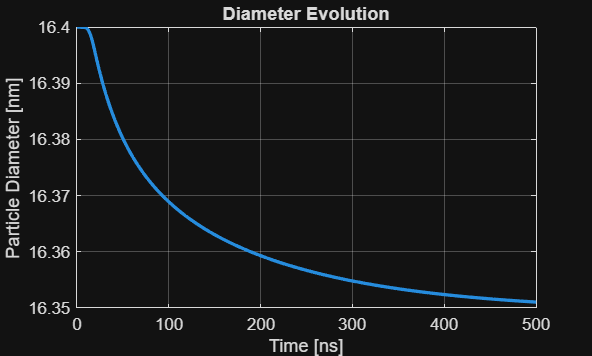


figure
plot(t*1e9, Dp*1e7, 'LineWidth', 2)
xlabel('Time [ns]')
ylabel('Particle Diameter [nm]')
title('Diameter Evolution')
grid on

LII Signal, we use top hat laser profile assumption, so no variation in radial direction.

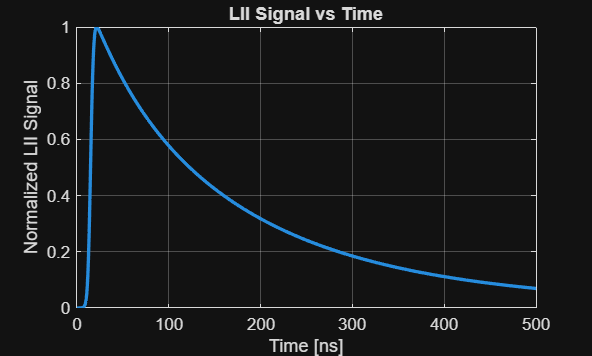

S_LII = compute_LII_signal(Tp,Dp,Nd,params);
S_LII = S_LII ./ max(S_LII);

figure
plot(t*1e9,S_LII,'LineWidth',2)
xlabel('Time [ns]')
ylabel('Normalized LII Signal')
title('LII Signal vs Time')
xlim([0 500])
grid on

Peak LII vs Fluence

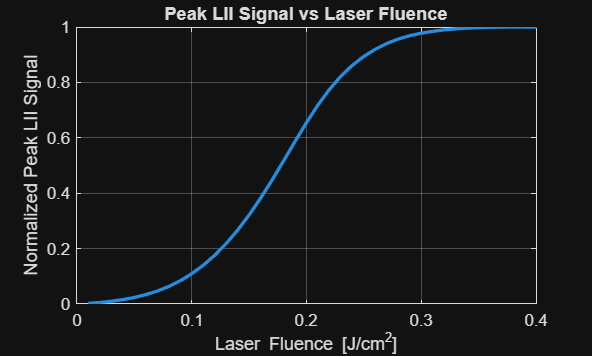

F_range = linspace(0.01,0.4,40);

peak_LII = zeros(size(F_range));


for j = 1:length(F_range)

    params_temp = params;
    params_temp.F = F_range(j);
    Nc0_temp = (pi/6) .* params_temp.Dp.^3 .* params_temp.rho_s(params_temp.Tg) .*params_temp.NA ./12.011;
    Nd0_temp = params_temp.Xd .* Nc0_temp;
    Y0 = [params_temp.Tg;params_temp.Dp;Nd0_temp];

    [t_temp,Y_temp] = ode15s(  @(t,Y) LII_odes(t,Y,params_temp),tspan,Y0,opts);

    Tp_temp = Y_temp(:,1);
    Dp_temp = Y_temp(:,2);
    Nd_temp = Y_temp(:,3);

    S_temp = compute_LII_signal(Tp_temp,Dp_temp,Nd_temp,params_temp);

    gate_start = 0e-9;
    gate_end   = 50e-9;
    gate_idx = (t_temp >= gate_start) & (t_temp <= gate_end);
    
    % Time-integrated LII signal
    peak_LII(j) = trapz(t_temp(gate_idx), S_temp(gate_idx));

end
peak_LII = peak_LII ./ max(peak_LII);

figure
plot(F_range,peak_LII,'LineWidth',2)
xlabel('Laser Fluence [J/cm^2]')
ylabel('Normalized Peak LII Signal')
title('Peak LII Signal vs Laser Fluence')
grid on

LII Signal Function

function S = compute_LII_signal(Tp,Dp,Nd,params)

h = 6.626e-34;
c = params.c;

lambda_det = linspace(600e-7,620e-7,1000);

S = zeros(size(Tp));

for i = 1:length(Tp)

    Tp_i = Tp(i);
    Dp_i = Dp(i);

    Nc_i = (pi/6) .*Dp_i.^3 .*params.rho_s(Tp_i) .* params.NA ./ 12.011;
    Xa_i = 1 - Nd(i) ./ (params.Xd .* Nc_i);
    Xa_i = max(0,min(1,Xa_i));

    Cabs_s_i = (1 - Xa_i) .*(pi^2 .* Dp_i.^3 ./ params.lambda_l) .* params.E_m .* params.Np;
    Cabs_a_i = Xa_i .*(pi^2 .* Dp_i.^3 ./ params.lambda_l) .*params.fa .*params.Ea_m .* params.Np;

    integrand = ((Cabs_s_i + Cabs_a_i) ./(lambda_det.^5)) .*((1 ./(exp((h*c) ./(lambda_det .* params.kB .* Tp_i)) - 1)) -(1 ./ (exp((h*c) ./(lambda_det .* params.kB .* params.Tg)) - 1)));

    S(i) = 8 .* pi .* h .* c.^2 .* trapz(lambda_det,integrand);
end
end

Helper function for sublimation

function J = sublimation_J(xi)

if xi <= 0.003
    J = xi;
elseif xi <= 0.05
    J = 0.92267 .* xi.^0.98535;
elseif xi <= 300
    lx = log(xi);
    J = 5.815e-1 + 3.496e-1 * lx + 6.516e-2 * lx^2 + 1.667e-3 *lx^3 - 6.031e-4 *lx^4 - 4.161e-5 * lx^5;
else
    J = -1.189 + 9.187e-1 * log(xi);
end
end

Sublimation full function

function [dMpdt_sub,Qsub] = lemaire_sublimation(Tp,Dp,Xa,Nc,k_lambda_s,k_lambda_a,params)
Pg = params.Pg;
Rp = params.Rp;
Rm = params.Rm;
R  = params.R;
kp = params.kp;
if Tp < params.Tg + 10
    dMpdt_sub = 0;
    Qsub = 0;
    return
end

species = [2 3];
Wj      = [24.022 36.033];  % g/mol
sigma_j = [2.4e-15 4.5e-15];  % cm^2
alpha_j = [0.5 0.1];
A0 = [params.A0_C2 params.A0_C3];
A1 = [params.A1_C2 params.A1_C3];
dHj = [params.dH_C2(Tp) params.dH_C3(Tp)];
Tcj = [params.Tc_C2 params.Tc_C3];
P_lambda_s = zeros(1,2);
P_lambda_a = zeros(1,2);

j = 1;

P_lambda_s(j) = (kp * Tp * k_lambda_s) ./ (pi * Dp.^2 * alpha_j(j)) .* sqrt((2*pi*Wj(j)) ./ (Rm * Tp));
P_lambda_a(j) = (kp * Tp * k_lambda_a) ./ (pi * Dp.^2 * alpha_j(j)) .* sqrt((2*pi*Wj(j)) ./ (Rm * Tp));
P_diss = zeros(1,2);

for j = 1:2
    P_diss(j) = Xa .*(kp .* Tp .* Nc) ./(2 .* pi .* Dp.^2 .* alpha_j(j)).*sqrt((2 .* pi .* Wj(j)) ./(Rm .* Tp)).*params.kdiss(Tp);
end
Psat = zeros(1,2);

for j = 1:2
    Peq = params.Pref .* exp((-dHj(j) ./ R) .* ((1./Tp) - (1./Tcj(j))) );

    if species(j) == 2
        Pphot = P_lambda_s(j) + P_diss(j) + P_lambda_a(j);
        if Peq < Pphot
            Psat(j) = Pphot;
        else
            Psat(j) = Peq;
        end
    else
        Psat(j) = Peq;
    end
end
Deff = zeros(1,2);

for j = 1:2

    numerator = (Tp + A0(j)/A1(j)).^2 - (params.Tg + A0(j)/A1(j)).^2;
    denominator = sqrt(Tp) .* (Tp + 3*A0(j)/(2*A1(j)))-sqrt(params.Tg) .* (params.Tg + 3*A0(j)/(2*A1(j)));
    if abs(denominator) < 1e-30
        denominator = 1e-30;
    end
    Deff(j) = (3 * params.f * kp * Tp) ./ (4 * sigma_j(j) * Pg) .* sqrt(Rm ./ (pi * Wj(j))) .*(numerator ./ denominator);
end

eta = zeros(1,2);

Psat_sum = sum(Psat);

for j = 1:2
    eta(j) = (1 ./ Psat(j)) .* (Pg + Psat_sum);
end

xi = zeros(1,2);

for j = 1:2
    prefactor = (Dp * alpha_j(j)) ./ (2 * Deff(j));
    thermal = sqrt((Rm * Tp) ./ (2*pi*Wj(j)));
    exponent = prefactor .* thermal .*(1 - eta(j) * Psat(j) ./ Pg);
    xi(j) = prefactor .*thermal .* exp(exponent);
end

Jxi = zeros(1,2);
for j = 1:2
    Jxi(j) = sublimation_J(xi(j));
end

Psurf = zeros(1,2);
for j = 1:2
    Psurf(j) = (Pg ./ eta(j)) .*(1 - ((2 * Deff(j)) ./ (Dp * alpha_j(j))).* sqrt((2*pi*Wj(j)) ./ (Rm * Tp)).* Jxi(j));
end

Bj = zeros(1,2);
for j = 1:2
    ratio = Psat(j) ./ Pg;
    if ratio < 0.003
        Bj(j) = ( 2 .* Deff(j) .* Psat(j))./ ( Dp .* alpha_j(j).* sqrt((Rm .* Tp) ./(2 .* pi .* Wj(j))) + 2 .* Deff(j));
    else
        Bj(j) = Psat(j) - Psurf(j);
    end
end
dMpdt_species = zeros(1,2);
for j = 1:2
    dMpdt_species(j) = -(pi .* Dp.^2 .* Wj(j) .*alpha_j(j) .* Bj(j))./ (Rp * Tp).*sqrt((Rm * Tp) ./ (2*pi*Wj(j)));
end

dMpdt_sub = sum(dMpdt_species);
Qsub = 0;

for j = 1:2
    numerator = dHj(j) .* (Psat(j)- P_lambda_s(j) - P_diss(j) - P_lambda_a(j))+params.dH_lambdan_s .* P_lambda_s(j)+params.dH_diss(Tp) .* P_diss(j) + params.dH_lambdan_a .* P_lambda_a(j);
    bracket_term = numerator ./ Psat(j);
    Qsub = Qsub - (1 ./ Wj(j)) .* dMpdt_species(j) .*bracket_term;
end
Qsub = params.Np .* Qsub;
end